# Load Matlab datafile

clear all;
load(fullfile('ECG.mat'));
%load(fullfile('ECGNEW.mat'));
%load(fullfile('PPG.mat'));
%load(fullfile('GSR.mat'));
%load(fullfile('ECGPPG.mat'));
%load(fullfile('ECGGSR.mat'));
%Data = importdata('TT2.csv');
%Data = importdata('ECGACC.csv');

%TrainTestData = Data.data;
%train_n_test_label = Data.textdata;

TrainTestData = Data.Data;
train_n_test_label = Data.Labels;
%TrainTestData=[TrainD(2:end),TestD(2:end)]
%train_n_test_label=[TrainD(1:), TestD(1:)]



## Split data into testing and training set

%trainData1 = TrainTestData(:,1:30000);
%testData1 = TrainTestData(:,30001:60000);
trainData1 = TrainTestData(:,1:8000);
testData1 = TrainTestData(:,8001:16000);

## Feature extraction

%timeWindow = 8192;
timeWindow = 400;
%timeWindow = 1000;
AROrder = 4;
transformLevel = 4;
%[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData,testData,timeWindow,AROrder,transformLevel);
[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData1,testData1,timeWindow,AROrder,transformLevel);
allFeatures = [trainFeatures;testFeatures];
allLabels = [train_n_test_label;train_n_test_label];

%allLabels = [train_n_test_labelCopy;train_n_test_labelCopy];



features = [trainFeatures; testFeatures];

## classification

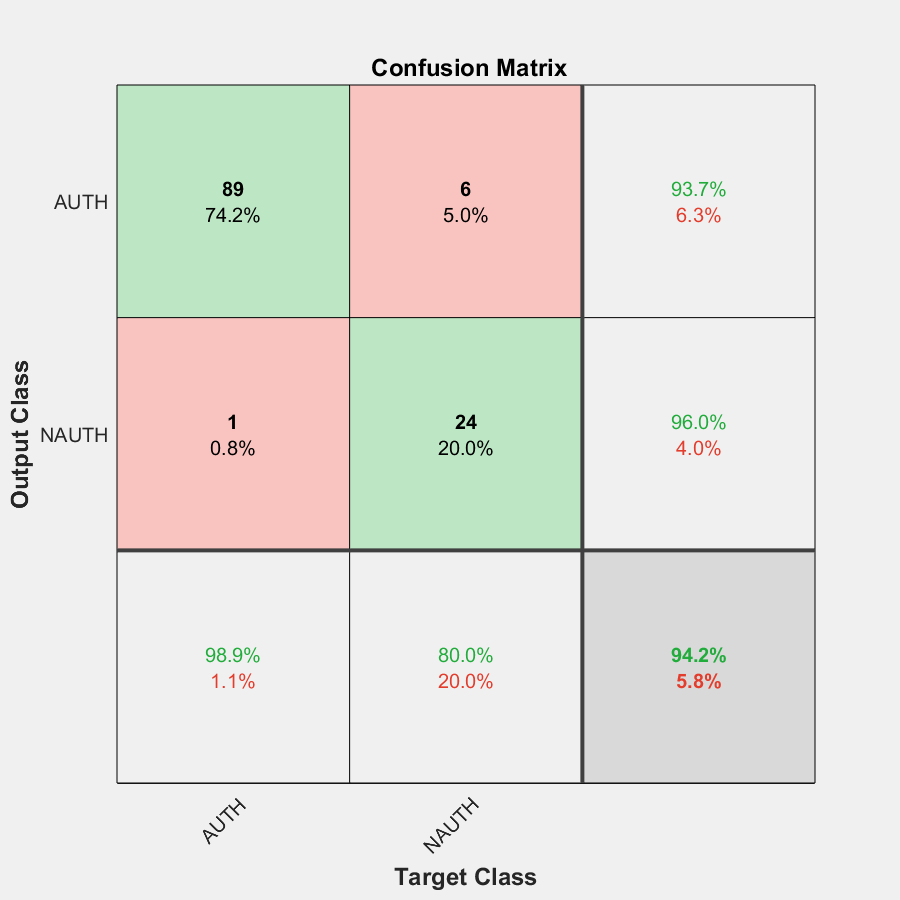

rng(1)
template = templateSVM(...
    'KernelFunction','polynomial',...
    'KernelScale','auto',...
    'BoxConstraint',1,...
    'Standardize',true);

% model = fitcecoc(...
%      trainFeatures,...
%      trainLabel,...
%      'Learners',template,...
%      'Coding','onevsone',...
%      'ClassNames',{'AUTH','NAUTH'});

model = fitcecoc(...
     trainFeatures,...
     train_n_test_label,...
     'Learners',template,...
     'Coding','onevsone', ...
     'ClassNames',{'AUTH','NAUTH'});

predLabels = predict(model,testFeatures);

%correctPredictions = strcmp(predLabels,testLabel);
correctPredictions = strcmp(predLabels,train_n_test_label);
[confusionMatrix] = confusionmat(train_n_test_label,predLabels);
plotconfusion(categorical(train_n_test_label),categorical(predLabels));

## calculate prediction results

truePositive = confusionMatrix(1,1);
falsePositive = sum(confusionMatrix(:,1)) - confusionMatrix(1,1);
falseNegative = sum(confusionMatrix(1,:)) - confusionMatrix(1,1);
trueNegative = confusionMatrix(2,2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
trueNegativeRate = trueNegative / (trueNegative+falsePositive);
falseNegativeRate = falseNegative / (falseNegative+truePositive);
falsePositiveRate= 1 - trueNegativeRate;
f1 = 2 * precision * recall / (precision + recall);

## display result

%testAccuracy = sum(correctPredictions) / length(testLabel)*100
testAccuracy = sum(correctPredictions) / length(train_n_test_label)*100

testAccuracy = 94.1667


confusionMatrixTable = array2table([truePositive falsePositive;...
    falseNegative trueNegative],'VariableNames',{'Positive','Negative'},'RowNames',...
    {'Positive','Negative'});

resultTable = array2table([precision recall f1 trueNegativeRate ...
    falseNegativeRate falsePositiveRate],'VariableNames',{'Precision','Recall','F1_Score',...
    'True Negative Rate', 'False Negative Rate', 'False Positive Rate' },'RowNames',...
    {'value',});

disp(confusionMatrixTable);

                Positive    Negative
                ________    ________

    Positive       89           6   
    Negative        1          24   



disp(resultTable);

             Precision    Recall     F1_Score    True Negative Rate    False Negative Rate    False Positive Rate
             _________    _______    ________    __________________    ___________________    ___________________

    value     0.93684     0.98889    0.96216            0.8                 0.011111                  0.2        

